# Control a Water Tank Level

Consider a cylindrical tank with no outlet flow and an adjustable inlet flow that is controlled by a valve. The inlet flow rate is not measured but there is a level measurement that shows how much fluid has been added to the tank. The objective of this exercise is to develop a controller that can maintain a certain water level by automatically adjusting the inlet flow rate.

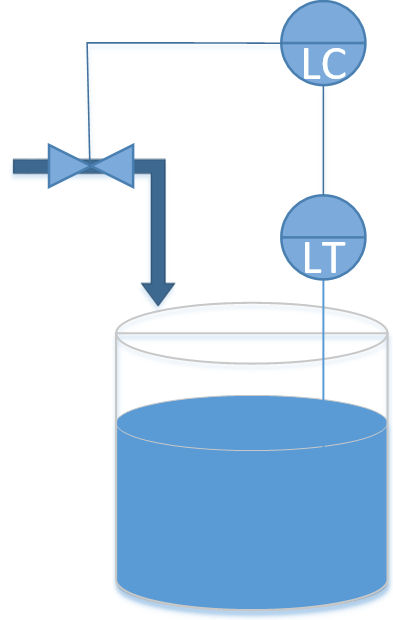

Note: The symbol **LT** is an abbreviation for *Level Transmitter*. A concentration sensor is typically shown as **CT** for *Concentration Transmitter* or **AT** for *Analyzer Transmitter*. A temperature sensor such as a thermocouple is shown as **TT** which stands for *Temperature Transmitter*. If the second letter is **C** then it is a controller such as **LC** for *Level Controller*.

This example continues from the introduction to modeling where the process equation is derived and sample Python code is available.


$$\rho A \frac{dh}{dt} = cu\ with\ \dot{m}_{in}=cu$$


where *c* is a constant that relates valve opening to inlet flow.

Design a[**r**](https://apmonitor.com/pdc/index.php/Main/ProportionalControl) P-only Controller for the tank to maintain a level set point of *10.0 m*. Test the P-only controller with different values of $K_c$ by integrating the mass balance equation for a period of 10 seconds. Use a value of 1000 kg/m3 for density and 1.0 $m^2$ for the cross-sectional area of the tank. For the valve, assume a valve coefficient of c=50.0 (kg/s / percent open). Make sure that the valve does not exceed the limits of 0-100 percent by clipping the requested valve opening to an acceptable range. For example, if the P-only controller calculates a valve opening of 150 percent, use 100 percent instead.

% time span for the simulation for 10 sec, every 0.1 sec
ts = linspace(0,10,101);

% valve operation
c = 50.0;          % valve coefficient (kg/s / %open)
u = zeros(101,1); % u = valve % open

% level initial condition
Level0 = 0;

% initial valve position
valve = 0;

% for storing the results
z = zeros(101,1);
es = zeros(101,1);
sps = zeros(101,1);

% TO DO: what is the value for ubias?
ubias = 0;

% TO DO: decide on a tuning value for Kc
Kc = 50.0;

% TO DO: record the desired level (set point)
SP = 10;

% simulate with ODEINT
for i=1:100
    % calculate the error
    error = SP - Level0;

    % TO DO: put P-only controller here
    valve =  ;
    
    % Limit valve to within 0 and 100
    valve = max(0,valve);
    valve = min(100,valve);

    u(i+1) = valve;   % store the valve position
    es(i+1) = error;  % store the error
    [~,y] = ode45(@(t,y) tank(t,y,c,valve),[0 0.1],Level0);
    Level0 = y(end); % take the last point
    z(i+1) = Level0; % store the level for plotting
    sps(i+1) = SP;
end


% plot results
subplot(3,1,1)
plot(ts,z,'-r','LineWidth', 3,'DisplayName','level PV'); hold on
plot(ts,sps,'k:','LineWidth', 3,'DisplayName','level SP'); hold off
ylabel('Tank Level');
legend();

subplot(3,1,2);
plot(ts,u,'--b','LineWidth', 3,'DisplayName','valve');
ylabel('Valve');
legend();

subplot(3,1,3);
plot(ts,es,'-g','LineWidth', 3,'DisplayName','error');
ylabel('Error = SP-PV');
xlabel('Time (sec)');
legend();

## Tank Model

function dLevel_dt = tank(~,~,c,valve)
    rho = 1000.0; % water density (kg/m^3)
    A = 1.0;      % tank area (m^2)
    % calculate derivative of the Level
    dLevel_dt = (c/(rho*A)) * valve;
end